# 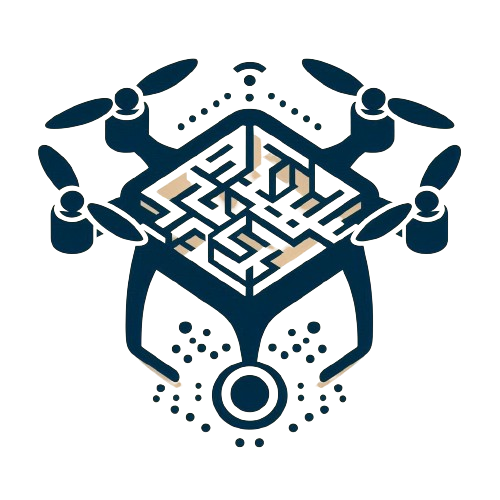

LiDflAIR    Tonelli-Zumerle

# Statistics simulations

All the previous simulations results in terms of coverage ratio are collected and plotted

Data saved from each simulation consist in |n° of drones | time of exploration | % map discovered

% Collects all simulation results from its root
sim_matrix = [];

directory = 'Simulation_data';

fileList = dir(fullfile(directory, 'data_sim_*.txt'));

for k = 1:length(fileList)
    fileName = fullfile(directory, fileList(k).name);
    data_sim = dlmread(fileName, ';');
    sim_matrix = [sim_matrix; data_sim];
end

Plot the data obtained to visualize the trend

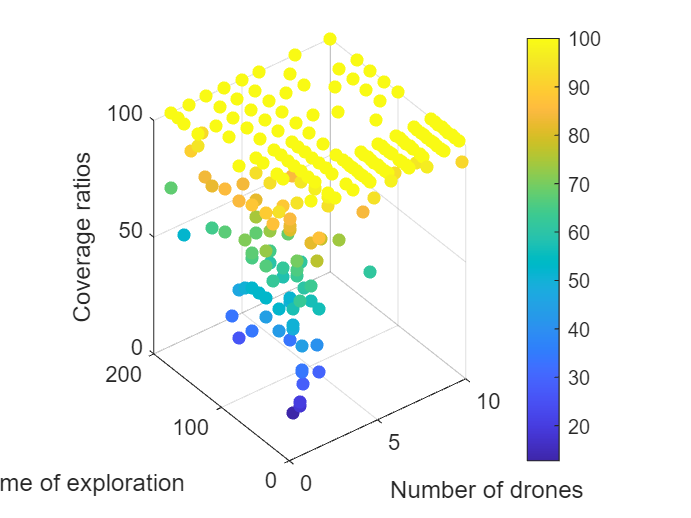

% Seprate the data
x = sim_matrix(:, 1);
y = sim_matrix(:, 2);
z = sim_matrix(:, 3);

% Plot the data
s = scatter3(x, y, z, [], z, 'filled');
colorbar;
xlabel('Number of drones');
ylabel('Time of exploration');
zlabel('Coverage ratios');
zlim([0 100]);


% Generate a single row for each of the combination discovered: if there
% are more, compute the average of the coverage ratio
[uniqueGroups, ~, idx] = unique(sim_matrix(:, 1:2), 'rows');
meanValues = accumarray(idx, sim_matrix(:, 3), [], @mean);

% Reorder the data in a new matrix
mean_matrix = [uniqueGroups, meanValues];
x = mean_matrix(:, 1);
y = mean_matrix(:, 2);
z = mean_matrix(:, 3);

% Generate a fit model able to approximate the trend. Chosen a fourth order
ft = fittype('poly44'); 
fo = fitoptions('Method','LinearLeastSquares','Normalize','on');
fitresult = fit([x, y], z, ft, fo)

     Linear model Poly44:
     fitresult(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p30*x^3 
                    + p21*x^2*y + p12*x*y^2 + p03*y^3 + p40*x^4 + p31*x^3*y 
                    + p22*x^2*y^2 + p13*x*y^3 + p04*y^4
       where x is normalized by mean 5.161 and std 2.968
       and where y is normalized by mean 72.98 and std 60.33
     Coefficients (with 95% confidence bounds):
       p00 =       100.4  (96.89, 103.9)
       p10 =    -0.09303  (-3.904, 3.718)
       p01 =      -2.235  (-6.998, 2.528)
       p20 =      -5.798  (-11.35, -0.2464)
       p11 =      -3.571  (-7.58, 0.4382)
       p02 =     -0.3721  (-4.596, 3.852)
       p30 =       6.848  (4.832, 8.863)
       p21 =       3.977  (2.067, 5.887)
       p12 =       2.286  (-0.2366, 4.809)
       p03 =       4.206  (0.2801, 8.132)
       p40 =      -2.348  (-4.585, -0.1123)
       p31 =      -1.081  (-2.872, 0.7103)
       p22 =     0.06036  (-1.592, 1.713)
       p13 =      -0.887  (-2.486, 0.712)
 

coeffs = coeffvalues(fitresult)'

coeffs =   100.3837
   -0.0930
   -2.2350
   -5.7977
   -3.5711
   -0.3721
    6.8479
    3.9771
    2.2861
    4.2062



% Residual calculus
zFit = feval(fitresult, x, y);
residuals = z - zFit;

% Information about the fitting obtained
SS_residual = sum(residuals.^2);
SS_total = sum((z - mean(z)).^2);
R2 = 1 - (SS_residual / SS_total);
mse = mean(residuals.^2);

fprintf('R^2: %f\n', R2);

R^2: 0.842095


fprintf('Mean Squared Error (MSE): %f\n', mse);

Mean Squared Error (MSE): 47.703445


fprintf('Root Mean Squared Error (MSE): %f\n', sqrt(mse));

Root Mean Squared Error (MSE): 6.906768


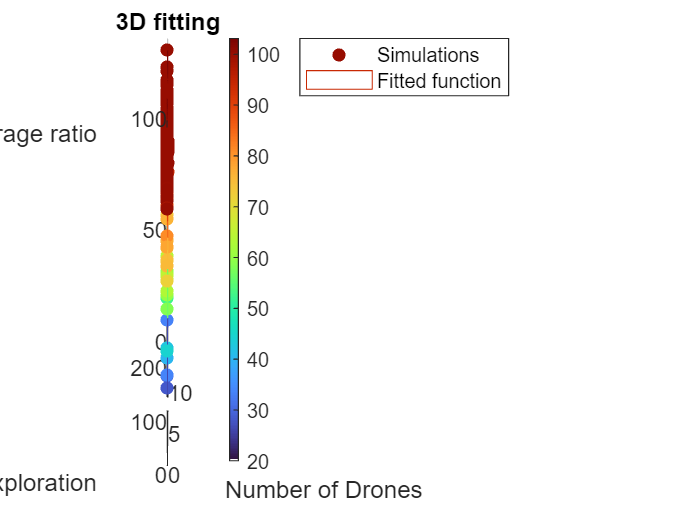


% Plot dei dati originali
figure;
scatter3(x, y, z, [], z, 'filled');
cmap = turbo(256);
cmap(1, :) = 1;
colormap(cmap);
colorbar;
zlim([0 105]);
hold on;

% Grid creation for visualization
[x_grid, y_grid] = meshgrid(1:1:10,0:10:200);
z_fit = feval(fitresult, x_grid, y_grid);
% Plot of the fitted curve
mesh(x_grid, y_grid, z_fit);
xlabel('Number of Drones');
ylabel('Time of exploration');
zlabel('Coverage ratio');
title('3D fitting');
legend('Simulations', 'Fitted function');
hold off;

#### Estimate the coverage reatio for given number of drones and time of simulation

Select the number of drones to develope and the wanted time to explore to predict the coverage ratio

drone =3

drone = 3

time_of_simulation =30

time_of_simulation = 30

coverage_ratio_estimated = min(fitresult(drone, time_of_simulation), 100);

disp(['The estimated value of the coverage ratio of the map is: ', num2str(round(coverage_ratio_estimated)), ' %']);                 

The estimated value of the coverage ratio of the map is: 89 %
